%%%%% Bob Wilson & Anne Collins
%%%%% 2018
%%%%% Code to produce figure 2 in submitted paper "Ten simple rules for the
%%%%% computational modeling of behavioral data"


clear

addpath('./SimulationFunctions')
addpath('./AnalysisFunctions')
addpath('./HelperFunctions')

set up colors

global AZred AZblue AZcactus AZsky AZriver AZsand AZmesa AZbrick

AZred = [171,5,32]/256;
AZblue = [12,35,75]/256;
AZcactus = [92, 135, 39]/256;
AZsky = [132, 210, 226]/256;
AZriver = [7, 104, 115]/256;
AZsand = [241, 158, 31]/256;
AZmesa = [183, 85, 39]/256;
AZbrick = [74, 48, 39]/256;



% experiment parameters
T   = 105;         % number of trials
mu  = [0.8 0.2];    % mean reward of bandits
reversal_trials = [13:24, 36:47, 60:70, 83:94];

% number of repetitions for simulations
Nrep = 110;

% Model 1: Random responding
for n = 1:Nrep
    b = 0.5;
    [a, r] = simulate_M1random_v1(T, mu, b, reversal_trials);
    sim(1).a(:,n) = a;
    sim(1).r(:,n) = r;
end

% Model 2: Win-stay-lose-shift
for n = 1:Nrep
    epsilon = 0.1;
    [a, r] = simulate_M2WSLS_v1(T, mu, epsilon, reversal_trials);
    sim(2).a(:,n) = a;
    sim(2).r(:,n) = r;
end
% Model 3: Rescorla Wagner
for n = 1:Nrep
    alpha = 0.1;
    beta = 5;
    [a, r] = simulate_M3RescorlaWagner_v1(T, mu, alpha, beta, reversal_trials);
    sim(3).a(:,n) = a;
    sim(3).r(:,n) = r;
end

% Model 4: Choice kernel
%for n = 1:Nrep
%    alpha_c = 0.1;
%    beta_c = 3;
%    [a, r] = simulate_M4ChoiceKernel_v1(T, mu, alpha_c, beta_c);
%    sim(4).a(:,n) = a;
%    sim(4).r(:,n) = r;
%end

% Model 5: Rescorla-Wagner + choice kernel
%for n = 1:Nrep
%    alpha = 0.1;
%    beta = 5;
%    alpha_c = 0.1;
%    beta_c = 1;
%    [a, r] = simulate_M5RWCK_v1(T, mu, alpha, beta, alpha_c, beta_c);
%    sim(5).a(:,n) = a;
%    sim(5).r(:,n) = r;
%end

## win-stay-lose-shift analysisj

for i = 1:length(sim)
    for n = 1:Nrep
        sim(i).wsls(:,n) = analysis_WSLS_v1(sim(i).a(:,n)', sim(i).r(:,n)');
    end
    wsls(:,i) = nanmean(sim(i).wsls,2);
end

## Plot WSLS behavior for all models

figure(1); clf; hold on;
l = plot([0 1], wsls);
ylim([0 1])
set(l, 'marker', '.', 'markersize', 50, 'linewidth', 3)


legend({'M1: random' 'M2: WSLS' 'M3: RW' 'M4: CK' 'M5: RW+CK'}, ...
    'location', 'southeast')

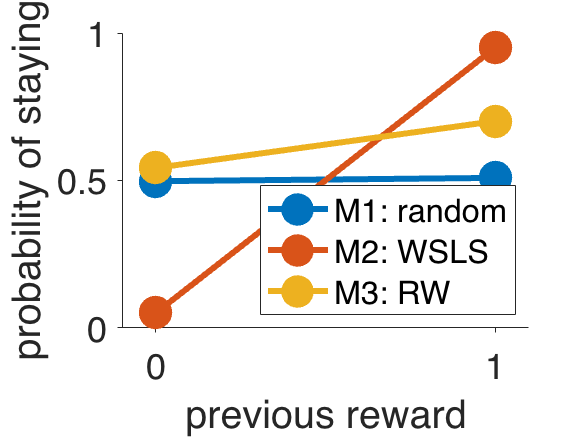

xlabel('previous reward')
ylabel('probability of staying')

set(gca, 'xtick', [0 1], 'tickdir', 'out', 'fontsize', 18, 'xlim', [-0.1 1.1])

## p(correct) analysis

alphas = [0.02:0.02:1];
betas = [1 2 5 10 20];

for n = 1:1000
    n;
    for i = 1:length(alphas)
        for j = 1:length(betas)
            [a, r] = simulate_M3RescorlaWagner_v1(T, mu, alphas(i), betas(j), reversal_trials);
            [~,imax] = max(mu);
            correct(i,j,n) = nanmean(a == imax);
            correctEarly(i,j,n) = nanmean(a(1:10) == imax);
            correctLate(i,j,n) = nanmean(a(end-9:end) == imax);
        end
    end
end

## plot p(correct) behavior

figure(1); 
E = nanmean(correctEarly,3);
L = nanmean(correctLate,3);

figure(1); clf; 
set(gcf, 'Position', [284   498   750   300])
ax = easy_gridOfEqualFigures([0.2 0.1], [0.08 0.14 0.05 0.03]);

axes(ax(1)); hold on;
l = plot([0 1], wsls);
ylim([0 1])
set(l, 'marker', '.', 'markersize', 50, 'linewidth', 3)
leg1 = legend({'M1: random' 'M2: WSLS' 'M3: RW' 'M4: CK' 'M5: RW+CK'}, ...
    'location', 'southeast');

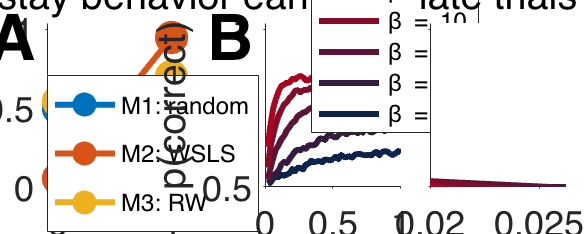

ans =   1×2 TextBox array:

    TextBox    TextBox


xlabel('previous reward')
% ylabel('probability of staying')
ylabel('p(stay)')
title('stay behavior', 'fontweight', 'normal')
xlim([-0.1 1.1]);
ylim([0 1.04])
set(ax(1), 'xtick', [0 1])
set(leg1, 'fontsize', 12)
set(leg1, 'position', [0.19    0.2133    0.1440    0.2617])
set(ax(1), 'ytick', [0 0.5 1])

axes(ax(2)); hold on;
l1 = plot(alphas, E);
xlabel('learning rate, \alpha')
ylabel('p(correct)')
title('early trials', 'fontweight', 'normal')

for i = 1:length(betas)
    leg{i} = ['\beta = ' num2str(betas(i))];
end
leg2 = legend(l1(end:-1:1), {leg{end:-1:1}});

set([leg1 leg2], 'fontsize', 12)
set(leg2, 'position', [0.6267    0.6453    0.1007    0.2617]);

axes(ax(3)); hold on;
l2 = plot(alphas, L);
xlabel('learning rate, \alpha')
% ylabel('p(correct)')
title('late trials', 'fontweight', 'normal')
for i = 1:length(l1)
    f = (i-1)/(length(l1)-1);
    set([l1(i) l2(i)], 'color', AZred*f + AZblue*(1-f));
end
set([l1 l2], 'linewidth', 3)
set(ax(3), 'yticklabel', [])

set(ax(2:3), 'ylim', [0.5 1.02])
set(ax, 'fontsize', 18, 'tickdir', 'out')
addABCs(ax(1:2), [-0.06 0.09], 32)